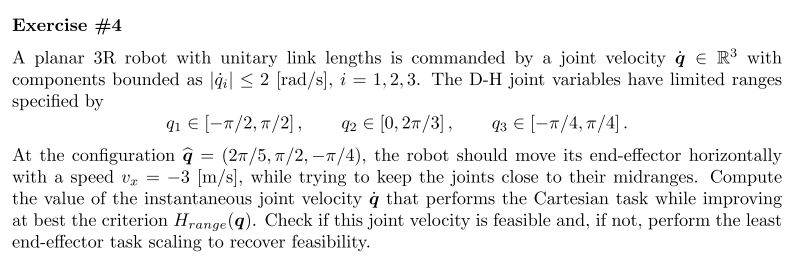

clc
clear all
close all

syms q1 q2 q3 real

r_dot=[-3 0]';
f=[cos(q1)+cos(q1+q2)+cos(q1+q2+q3);
   sin(q1)+sin(q1+q2)+sin(q1+q2+q3)];
q=[q1 q2 q3]';
q_bar=[2*pi/5 pi/2 -pi/4]';
q_max=[pi/2 2*pi/3 pi/4]';
q_min=[-pi/2 0 -pi/4]';
J=jacobian(f, q);
J_bar=subs(J, q, q_bar);
q0_t=H_range(q, q_max, q_min);
q0=subs(q0_t, q, q_bar)

$$q0 = \left(\begin{array}{c} -\frac{2}{15\,\pi }\\ -\frac{1}{8\,\pi }\\ \frac{1}{3\,\pi } \end{array}\right)$$

q_dot=vpa(q0+pinv(J_bar)*(r_dot-J_bar*q0))

$$q\_dot = \left(\begin{array}{c} 2.0638419570692035156738737347144\\ -1.9261185657606184440424377485897\\ 0.97855439419326029003313877194578 \end{array}\right)$$


s=min(abs([2 2 2]'./q_dot))

$$s = 0.96906645063081116278262845296018$$


q_dot_rescaled=s*q_dot

$$q\_dot\_rescaled = \left(\begin{array}{c} 2.0\\ -1.866536882015751157497393126236\\ 0.94828423353004639843548525987597 \end{array}\right)$$